clear all
syms I0 V0 R L C t real

syms i(t)

Di = diff(i,t)

$$Di(t) = \frac{\partial }{\partial t}i\left(t\right)$$

D2i = diff(i,t,2)

$$D2i(t) = \frac{\partial^{2}}{\partial t^{2}}i\left(t\right)$$


ode = R*Di + L*D2i + 1/C*i == 0

$$ode(t) = R\,\frac{\partial }{\partial t}i\left(t\right)+L\,\frac{\partial^{2}}{\partial t^{2}}i\left(t\right)+\frac{i\left(t\right)}{C}=0$$


% I0 : corrente no instante t=0
cond1 = i(0) == I0

$$cond1 = i\left(0\right)=I_{0}$$

% V0: tensão sobre o capacitor em t=0
% Aplicando a LKT: Vr+Vl+Vc=0
% R*i(t) + L*di(t)/dt + Vc(t) = 0
% R*I0 + L*di(0)/dt + V0 = 0
% di(0)/dt = -(R*I0+V0)/L
cond2 = Di(0) == -(R*I0+V0)/L

$$cond2 = \left({\left(\frac{\partial }{\partial t}i\left(t\right)\right)|}_{t=0}\right)=-\frac{V_{0}+I_{0}\,R}{L}$$


cond = [cond1, cond2]

$$cond = \left(\begin{array}{cc} i\left(0\right)=I_{0} & \left({\left(\frac{\partial }{\partial t}i\left(t\right)\right)|}_{t=0}\right)=-\frac{V_{0}+I_{0}\,R}{L} \end{array}\right)$$


i_solve = simplify( dsolve(ode, cond) )

$$i\_solve = \begin{array}{l} \frac{{\mathrm{e}}^{-\frac{t\,\left(\sigma_{1}+C\,R\right)}{2\,C\,L}}\,\left(I_{0}\,\sigma_{1}+2\,C\,V_{0}+C\,I_{0}\,R\right)}{2\,\sigma_{1}}-\frac{{\mathrm{e}}^{\frac{t\,\left(\sigma_{1}-C\,R\right)}{2\,C\,L}}\,\left(2\,C\,V_{0}-I_{0}\,\sigma_{1}+C\,I_{0}\,R\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{C^{2}\,R^{2}-4\,C\,L} \end{array}$$

i_solve = subs(i_solve, {R, L, C}, {0, 1, 1})

$$i\_solve = -\frac{{\mathrm{e}}^{-t\,\mathrm{i}}\,\left(2\,V_{0}+2\,I_{0}\,\mathrm{i}\right)\,\mathrm{i}}{4}-\frac{{\mathrm{e}}^{t\,\mathrm{i}}\,\left(-2\,V_{0}+2\,I_{0}\,\mathrm{i}\right)\,\mathrm{i}}{4}$$

i_solve = subs(i_solve, {V0, I0}, {-10, 0})

$$i\_solve = 5\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\mathrm{i}-5\,{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}$$

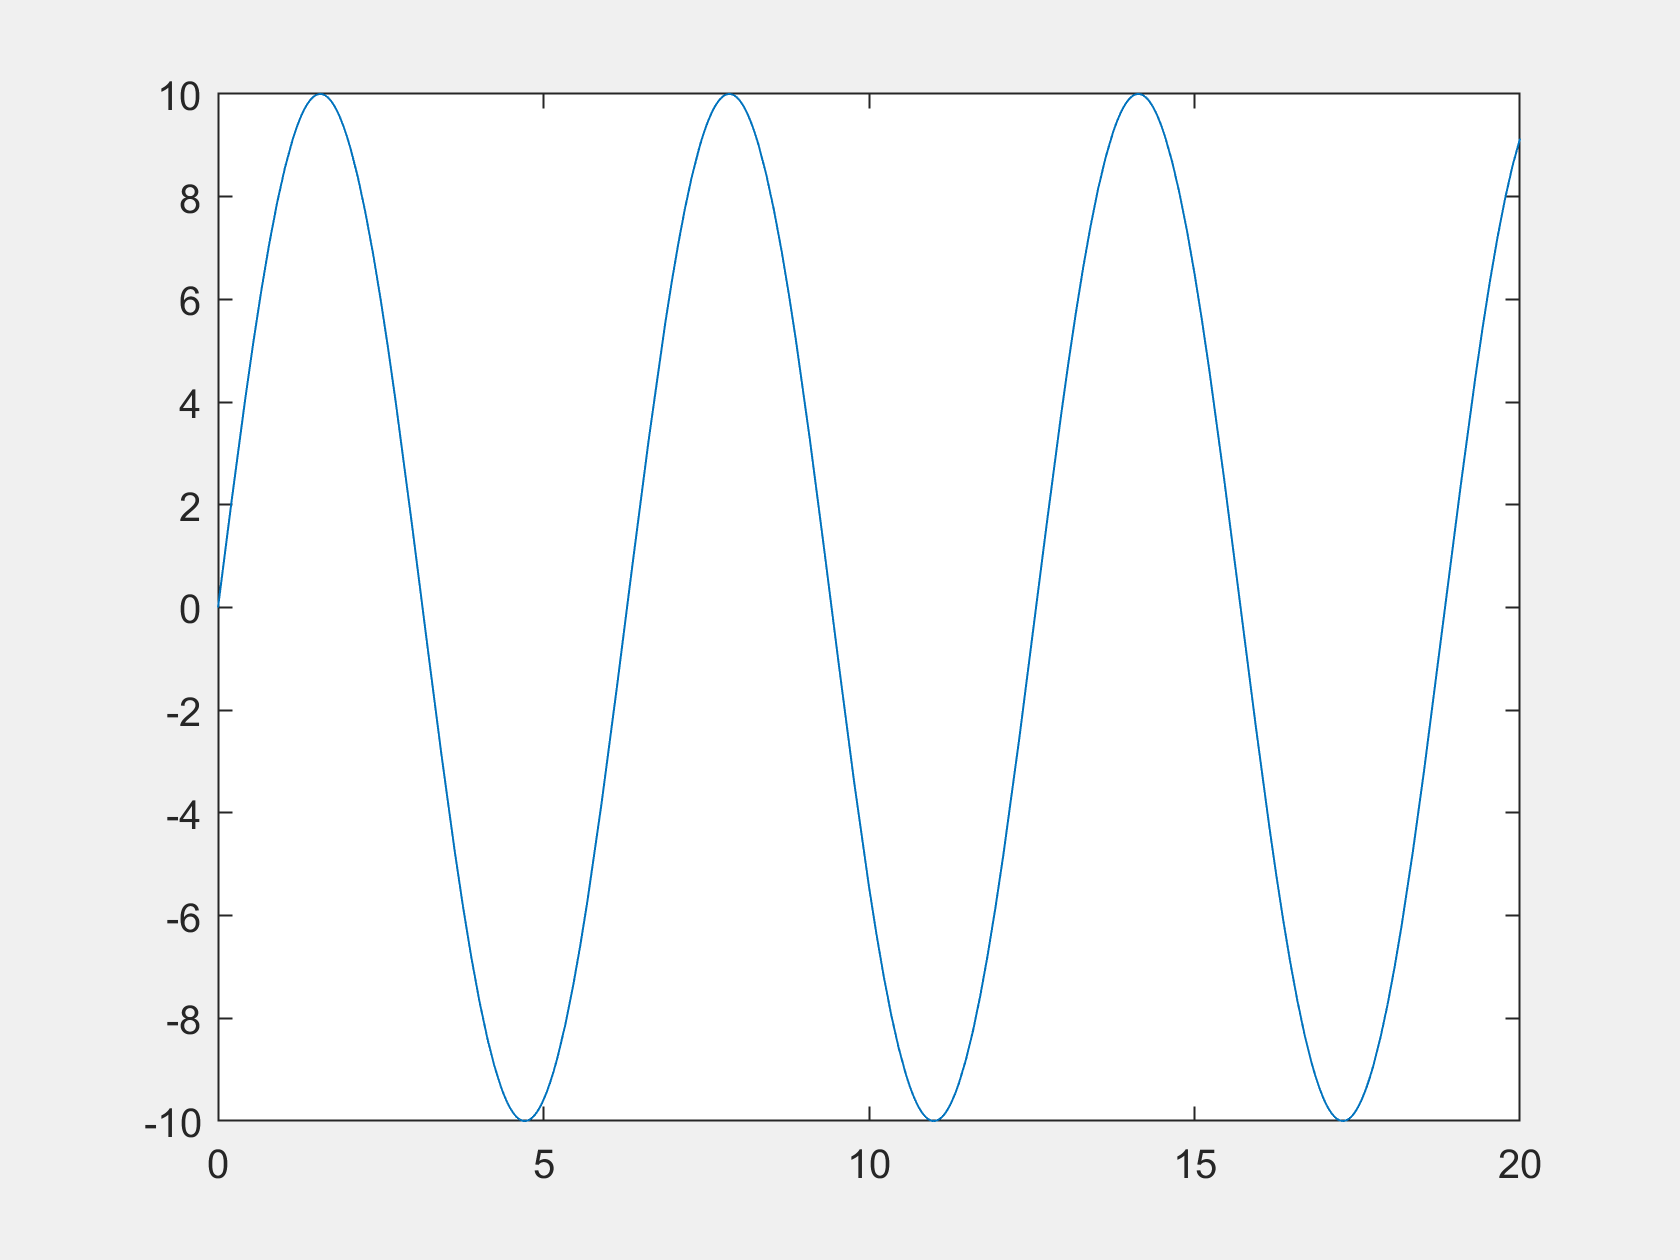

% Para plotar também em uma janela separada
set(gcf, 'Visible', 'On')
fplot(i_solve, [0 20])